# `Modelling and LQR Tunning `

## **Motor parameters**

 J = 0.0000881;
 Kb = 0.0089156;
 Kt = Kb;
 La = 0.057385;
 Ra = 430;
 b = 0.033322;

## **Mechanical System Parameters**

jr=0.000055425;
jp=0.000051301;
mp=0.031;
lr=120*10^(-3);
lp=132*10^(-3);
g=9.81;

## **State Space Representation**

c1=jr+mp*(lr^2);
c2=-0.5*mp*lr*lp;
c3=0.25*mp*(lp^2)+jp;
c4=-0.5*mp*lr*lp;
c5=-0.5 *mp*g*lp;
A22= 34^2*(c3*Kt*Kb)/(Ra*(c1*c3-c2*c4));
A23= c2*c5/(c1*c3-c2*c4);
A42= 34^2*c4*Kt*Kb/(Ra*(c1*c3-c2*c4));
A43= -c5/c3;

B2= c3*Kt/(Ra*(c1*c3-c2*c4));
B4=-c4*Kt/(Ra*(c1*c3-c2*c4));

A=[0 1 0 0; 0 A22 A23 0;
    0 0 0 1; 0 A42 A43 0];

B= [0; B2; 0; B4];
C=[ 1 0 0 0; 0 0 1 0];
D=[ 0; 0];

## **LQR **

Q =diag([0.1,1,40,50]);% Weighting matrix for states

R = 0.01; % Weighting matrix for control inputs


K = lqr(A,B,Q,R); % LQR gain matrix

K =    54.7723  157.2419  197.4907  -50.5565


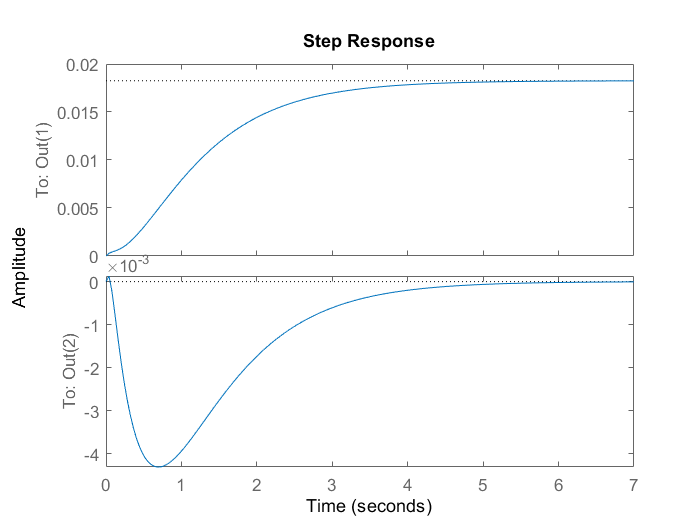



system=ss(A-B*K,B,C,0);

step(system);